# Task 2 Question 1

% controller specs: settling time, overshoot
Mp_max = 0.1

Mp_max = 0.1000

syms z wn
% use z instead of zeta

## calculate range for zeta (from overshoot)

eqn_Mp = exp(-pi*z/sqrt(1-z^2)) == Mp_max;
eqn_Mp

$$eqn\_Mp = {\mathrm{e}}^{-\frac{\pi \,z}{\sqrt{1-z^{2}}}}=\frac{1}{10}$$

% Compute analytic solution of the equation
sol_z = solve(eqn_Mp,z,'Real',true);
% displaySymSolution(sol_z);
% Compute numeric solution of the equation
sol_z = vpa(sol_z)

$$sol\_z = 0.59115503379889750930516375129716$$


% test if solution is a maximum or minimum value
eps = 0.01

eps = 0.0100

eqn_Mp_eps = exp(-pi*z/sqrt(1-z^2)) == Mp_max+eps;
eqn_Mp_eps

$$eqn\_Mp\_eps = {\mathrm{e}}^{-\frac{\pi \,z}{\sqrt{1-z^{2}}}}=\frac{11}{100}$$

sol_z_eps = solve(eqn_Mp_eps,z,'Real',true);
% Display symbolic solution returned by solve
%displaySymSolution(sol_z_eps);
% Compute numeric solution of the equation
sol_z_eps = vpa(sol_z_eps)

$$sol\_z\_eps = 0.57488784961246081708395635255255$$

if sol_z < sol_z_eps
    disp('sol_z is maximum z value')
elseif sol_z > sol_z_eps
    disp('sol_z is minimum z value')
end

sol_z is minimum z value


zmin = double(sol_z)

zmin = 0.5912

## calculate range for wn (from settling time)

ts_max = 45; %seconds
ineq_wn = 4.6/(z*wn) < ts_max

$$ineq\_wn = \frac{23}{5\,\mathrm{wn}\,z}<45$$

% Compute analytic solution of the inequality
sol = solve(ineq_wn,wn,'Real',true, 'ReturnConditions',true);
sol.wn

$$ans = x$$

sol.conditions

$$ans = \left(0<x\wedge z<0\right)\vee \left(x<0\wedge 0<z\right)\vee \left(x<\frac{23}{225\,z}\wedge z<0\right)\vee \left(\frac{23}{225\,z}<x\wedge 0<z\right)$$

## plot contour of solution

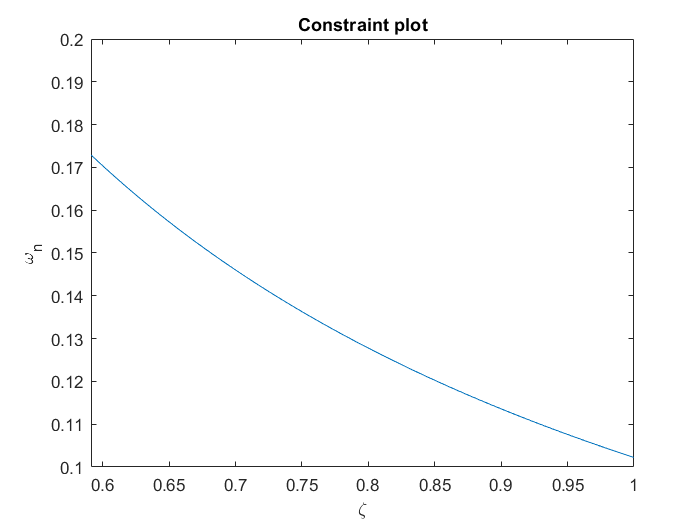

% overshoot only for zeta < 1 --> only plot for zeta <1  
x = linspace(zmin,1,100);
y = 23./(225*x);
figure
plot(x,y)
title('Constraint plot')
xlabel('\zeta')
ylabel('\omega_n')
axis([zmin, 1, 0.1, 0.2])

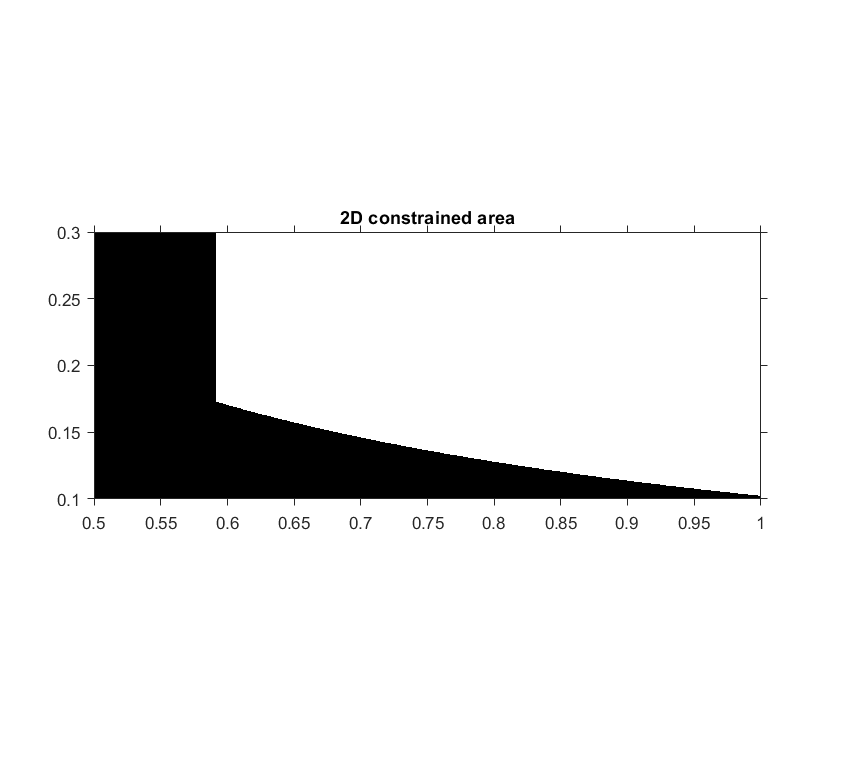

% plot constraints 2D
xdata = linspace(0.5,1,1000);
ydata = linspace(0.1,0.3,1000);
[x, y] = meshgrid(xdata,ydata);  % Get 2-D mesh for x and y based on r
condition1 = x > zmin;
condition2 = y > 23./(225*x);
output = ones(length(ydata),length(xdata)); % Initialize to 1
output(~(condition1 & condition2)) = 0; % Zero out coordinates not meeting conditions.
figure
imshow(output, 'xdata', xdata, 'ydata', ydata); % Display
axis on;
axis xy;
title('2D constrained area')

## closed loop system equation

minphase

% Symbolic calculation of T(s)
syms K1 K2 T1 T2 s...
    a1 a2 a3 a4...
    b1 b2 b3 b4...
    t1 t2 
%G_mp = [1.998/(30*s + 0.452049), 1.6658/((30*s+0.452049)*(30*s+0.994507));...
%         1.06561/((35*s+0.355639)*(35*s+0.800009)), 1.675/(35*s+0.355639)];
G_mp = [a1/(t1*s+b1), a2/((t1*s + b1)*(t1*s + b2));...
        a3/((t2*s+b3)*(t2*s+b4)), a4/(t2*s+b3)]

$$G\_mp = \left(\begin{array}{cc} \frac{a_{1}}{b_{1}+s\,t_{1}} & \frac{a_{2}}{\left(b_{1}+s\,t_{1}\right)\,\left(b_{2}+s\,t_{1}\right)}\\ \frac{a_{3}}{\left(b_{3}+s\,t_{2}\right)\,\left(b_{4}+s\,t_{2}\right)} & \frac{a_{4}}{b_{3}+s\,t_{2}} \end{array}\right)$$

         % G_mp = vpa(G_mp,4)
K = [K1*(1+1/(T1 * s)), 0;...
     0, K2*(1+1/(T2 * s))]

$$K = \left(\begin{array}{cc} K_{1}\,\left(\frac{1}{T_{1}\,s}+1\right) & 0\\ 0 & K_{2}\,\left(\frac{1}{T_{2}\,s}+1\right) \end{array}\right)$$

L_mp = G_mp * K;
% L_mp = vpa(expand(L_mp),4)
% T_mp = vpa(expand((eye(2)+L_mp)\L_mp),4)
% T_mp0 = vpa(subs(T_mp,s,0),6)
a1 = 1.998; a2 = 1.6658; a3 = 1.06561; a4 = 1.675;
b1 = 0.452049; b2 = 0.994507; b3 = 0.355639; b4 = 0.800009;
t1 = 30; t2 = 35;
% vpa(simplify(subs(expand(inv(L_mp))),'Steps',10),4)
% expression for T_mp is very long 
T_mp = vpa(subs(simplify(expand(inv(eye(2)+L_mp)*L_mp))),4)

$$T\_mp = \begin{array}{l} \left(\begin{array}{cc} \frac{K_{1}\,\left(T_{1}\,s+1.0\right)\,\left(0.8876\,K_{2}+196.8\,K_{2}\,s+0.5653\,T_{2}\,s+3514.0\,K_{2}\,s^{2}+97.42\,T_{2}\,s^{2}+4859.0\,T_{2}\,s^{3}+73430.0\,T_{2}\,s^{4}+0.8876\,K_{2}\,T_{2}\,s+196.8\,K_{2}\,T_{2}\,s^{2}+3514.0\,K_{2}\,T_{2}\,s^{3}\right)}{\sigma_{1}} & \frac{1.666\,K_{2}\,T_{1}\,s\,\left(T_{2}\,s+1.0\right)\,\left(35.0\,s+0.3556\right)\,\left(35.0\,s+0.8\right)}{\sigma_{1}}\\ \frac{1.066\,K_{1}\,T_{2}\,s\,\left(30.0\,s+0.452\right)\,\left(30.0\,s+0.9945\right)\,\left(T_{1}\,s+1.0\right)}{\sigma_{1}} & \frac{K_{2}\,\left(T_{2}\,s+1.0\right)\,\left(0.8876\,K_{1}+196.8\,K_{1}\,s+0.6024\,T_{1}\,s+3514.0\,K_{1}\,s^{2}+84.51\,T_{1}\,s^{2}+3750.0\,T_{1}\,s^{3}+52760.0\,T_{1}\,s^{4}+0.8876\,K_{1}\,T_{1}\,s+196.8\,K_{1}\,T_{1}\,s^{2}+3514.0\,K_{1}\,T_{1}\,s^{3}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.8876\,K_{1}\,K_{2}+196.8\,K_{1}\,K_{2}\,s+0.5653\,K_{1}\,T_{2}\,s+0.6024\,K_{2}\,T_{1}\,s+3514.0\,K_{1}\,K_{2}\,s^{2}+97.42\,K_{1}\,T_{2}\,s^{2}+84.51\,K_{2}\,T_{1}\,s^{2}+4859.0\,K_{1}\,T_{2}\,s^{3}+3750.0\,K_{2}\,T_{1}\,s^{3}+73430.0\,K_{1}\,T_{2}\,s^{4}+52760.0\,K_{2}\,T_{1}\,s^{4}+0.1279\,T_{1}\,T_{2}\,s^{2}+30.53\,T_{1}\,T_{2}\,s^{3}+2562.0\,T_{1}\,T_{2}\,s^{4}+89560.0\,T_{1}\,T_{2}\,s^{5}+1.102e+6\,T_{1}\,T_{2}\,s^{6}+196.8\,K_{1}\,K_{2}\,T_{1}\,s^{2}+3514.0\,K_{1}\,K_{2}\,T_{1}\,s^{3}+196.8\,K_{1}\,K_{2}\,T_{2}\,s^{2}+3514.0\,K_{1}\,K_{2}\,T_{2}\,s^{3}+0.5653\,K_{1}\,T_{1}\,T_{2}\,s^{2}+97.42\,K_{1}\,T_{1}\,T_{2}\,s^{3}+0.6024\,K_{2}\,T_{1}\,T_{2}\,s^{2}+4859.0\,K_{1}\,T_{1}\,T_{2}\,s^{4}+84.51\,K_{2}\,T_{1}\,T_{2}\,s^{3}+73430.0\,K_{1}\,T_{1}\,T_{2}\,s^{5}+3750.0\,K_{2}\,T_{1}\,T_{2}\,s^{4}+52760.0\,K_{2}\,T_{1}\,T_{2}\,s^{5}+0.8876\,K_{1}\,K_{2}\,T_{1}\,s+0.8876\,K_{1}\,K_{2}\,T_{2}\,s+0.8876\,K_{1}\,K_{2}\,T_{1}\,T_{2}\,s^{2}+196.8\,K_{1}\,K_{2}\,T_{1}\,T_{2}\,s^{3}+3514.0\,K_{1}\,K_{2}\,T_{1}\,T_{2}\,s^{4} \end{array}$$

disp('L_mp:')

L_mp:


vpa(subs(simplify(expand(L_mp))),4)

$$ans = \left(\begin{array}{cc} \frac{1.998\,K_{1}\,\left(T_{1}\,s+1.0\right)}{T_{1}\,s\,\left(30.0\,s+0.452\right)} & \frac{1.666\,K_{2}\,\left(T_{2}\,s+1.0\right)}{T_{2}\,s\,\left(30.0\,s+0.452\right)\,\left(30.0\,s+0.9945\right)}\\ \frac{1.066\,K_{1}\,\left(T_{1}\,s+1.0\right)}{T_{1}\,s\,\left(35.0\,s+0.3556\right)\,\left(35.0\,s+0.8\right)} & \frac{1.675\,K_{2}\,\left(T_{2}\,s+1.0\right)}{T_{2}\,s\,\left(35.0\,s+0.3556\right)} \end{array}\right)$$

## independent design

minphase (controller K_mp)

% Controller K11

K_mp11 = K1*(1+1/(T1 * s));
G_mp11 = G_mp(1,1);
L_mp11 = G_mp11 * K_mp11;
T_mp11 = (1+L_mp11)\L_mp11;
%visualize T_mp11
disp('T_mp11:')

T_mp11:


vpa(subs(simplify(expand(T_mp11))),6)

$$ans = \frac{1.998\,K_{1}\,\left(T_{1}\,s+1.0\right)}{1.998\,K_{1}+0.452049\,T_{1}\,s+30.0\,T_{1}\,s^{2}+1.998\,K_{1}\,T_{1}\,s}$$

% Controller design
run("quadtank_minphase.m");


 Operating point search report:
---------------------------------

 Operating point search report for the Model nlQuadtank.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) nlQuadtank/h1_state
      x:          12.1      dx:     -2.97e-08 (0)
(2.) nlQuadtank/h2_state
      x:          12.6      dx:     -5.19e-08 (0)
(3.) nlQuadtank/h3_state
      x:          2.51      dx:      1.02e-07 (0)
(4.) nlQuadtank/h4_state1
      x:          2.48      dx:      9.35e-08 (0)

Inputs: 
----------
(1.) nlQuadtan

G_mp = tf(sys_mp);
G11_mp = G_mp(1,1)

G11_mp =
 
  From input "u(1)" to output "Mux(1)":
    0.0666
  -----------
  s + 0.01506
 
Continuous-time transfer function.



zmin = 0.59116;
KN1 = 0.0666; % Numerator gain of G_mp(1,1)
p1 = -0.01506; % pole of G_mp(1,1)
factor =1; % factor for distance of zero and pole real part
K1min = (46/225 + p1)/KN1           % condition I (>)

K1min = 2.8436

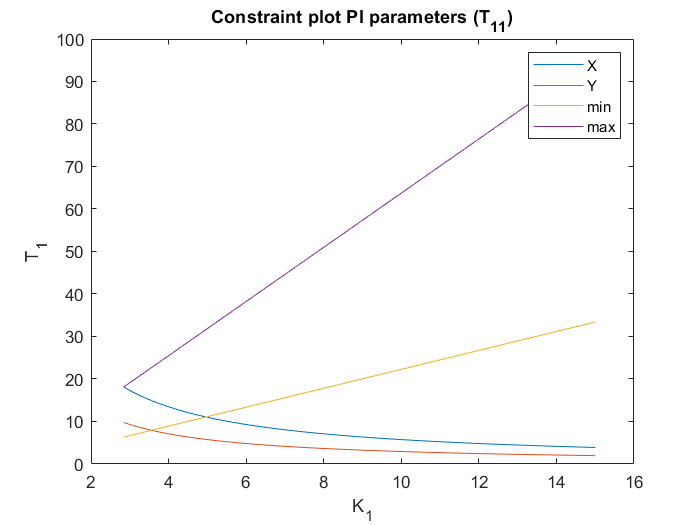

K1 = linspace(K1min,15,100);       % initialize K1 vector
T1_X = 4*(KN1*K1)./((KN1*K1-p1).^2); % condition X (<)
T1_Y = 2./(factor*(KN1*K1-p1));      % condition Y (<)
% T1_II = KN1*K1*(225/23)^2*zeta^2;        % condition II (<)
T1_min = KN1*K1*(225/23)^2*zmin^2;   % condition min (>)
T1_max = KN1*K1*(225/23)^2*1^2;   % condition max (>)
% T1_EQ = 4*(zeta^2)*KN1*K1./((KN1*K1-p1).^2); % condition EQ (=)

figure
plot(K1,T1_X,K1,T1_Y,K1,T1_min,K1,T1_max)
title('Constraint plot PI parameters (T_{11})')
xlabel('K_1')
ylabel('T_1')
legend ('X','Y','min','max')

%% Design Procedure:
% --> from graph: T1min = 6.3338 (min graph at K1 = K1min) 
% from max graph (zeta =1): higher T1 -> higher zeta -> lower overshoot
% Y graph: zero left of poles (real axis) --> not really feasible
% point (K1, T1) above Y graph --> zero significantly increases overshoot
% -> choose T1 > T1min 
% Choice 1: K1 = K1min = 2.8436, T1 = 2*T1min = 12.6676         --> OS = 13.66%, ts = 41.5s 
% Choice 2: K1 = 2.8436, T1 = 18 (below X and max graph)        -->OS = 9.78% , ts = 50.0s 
% (still ~10 % OS --> max and X constraints (guarantee that system has OS)
% are not accurate because zero increases OS anyways --> higher T1 possible
% Choice 3: K1 = 2.8436, T1 = 25                                --> OS = 6.63%, ts = 56.4s
% Choice 4: K1 = 6 (ca. 2*K1min), T1 = 25 (ca. 2*T1_min(@K=6))  --> OS = 4.06%, ts = 33.65s
%--------> Choice 4 has good distance to both OS and ts boundaries!  

% Test controller
s =tf('s');
K1 = 6

K1 = 6

%T1 = 20 *4*(zeta^2)*KN1*K1/((KN1*K1-p1)^2)
T1 = 25

T1 = 25

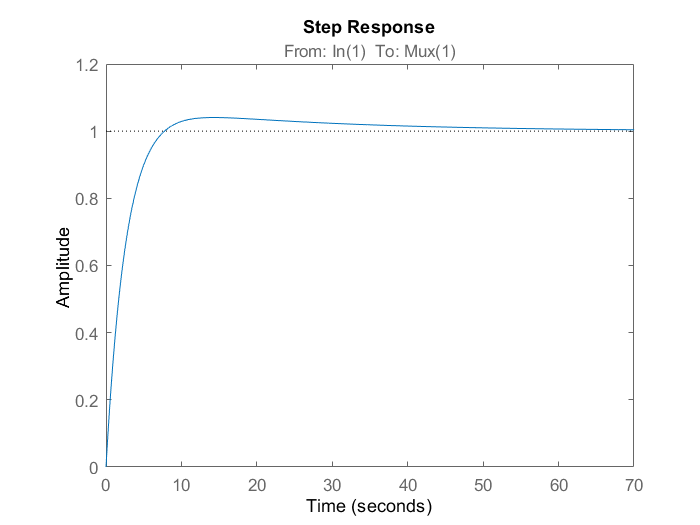

K11_mp = K1*(1+1/(T1*s));
T11_mp = feedback(G11_mp*K11_mp,1);
figure
step(T11_mp)

info = stepinfo(T11_mp)

info = struct with fields:
        RiseTime: 4.7480
    SettlingTime: 33.6505
     SettlingMin: 0.9041
     SettlingMax: 1.0406
       Overshoot: 4.0639
      Undershoot: 0
            Peak: 1.0406
        PeakTime: 14.2498


% Controller K22
G22_mp = G_mp(2,2)

G22_mp =
 
  From input "u(2)" to output "Mux(2)":
    0.04786
  -----------
  s + 0.01017
 
Continuous-time transfer function.



% Controller design
KN2 = 0.04786; % Numerator gain of G_mp(2,2)
p2 = -0.01017; % pole of G_mp(2,2)
factor =1; % factor for distance of zero and pole real part
K2min = (46/225 + p1)/KN2           % condition I (>)

K2min = 3.9571

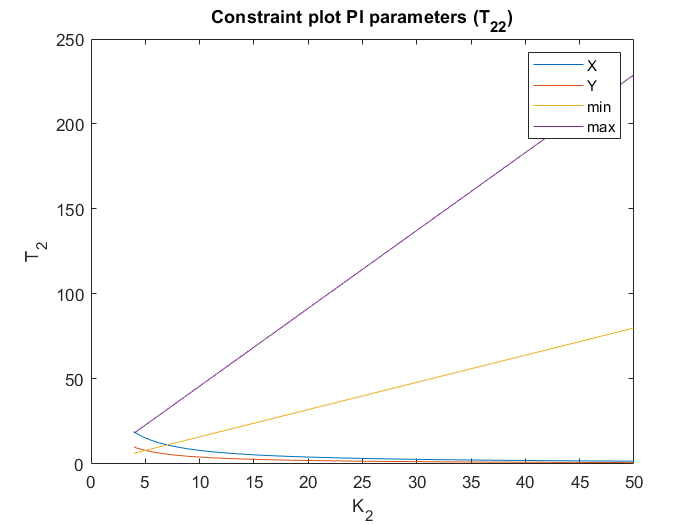

K2 = linspace(K2min,50,1000);       % initialize K1 vector
T2_X = 4*(KN2*K2)./((KN2*K2-p2).^2); % condition X (<)
T2_Y = 2./(factor*(KN2*K2-p2));      % condition Y (<)
% T2_II = KN2*K2*(225/23)^2*zeta^2;        % condition II (<)
T2_min = KN2*K2*(225/23)^2*zmin^2;   % condition min (>)
T2_max = KN2*K2*(225/23)^2*1^2;   % condition max (>)
% T1_EQ = 4*(zeta^2)*KN1*K1./((KN1*K1-p1).^2); % condition EQ (=)

figure
plot(K2,T2_X,K2,T2_Y,K2,T2_min,K2,T2_max)
title('Constraint plot PI parameters (T_{22})')
xlabel('K_2')
ylabel('T_2')
legend ('X','Y','min','max')

%% Design Procedure:
% K2min = 3.9571; --> from graph: T2min = 6.3338 (min graph at K2 = K2min) 
% Learn from design of K11!
% Choice 1: K2 = 8 (ca. 2*K2min), T2=25 (ca. 2*T2_min(@K2=8) --> OS = 13.66%, ts = 41.5s
%--------> Choice 1 has good distance to both OS and ts boundaries!  

% Test controller
% s =tf('s');
K2 = 8

K2 = 8

T2 = 25

T2 = 25

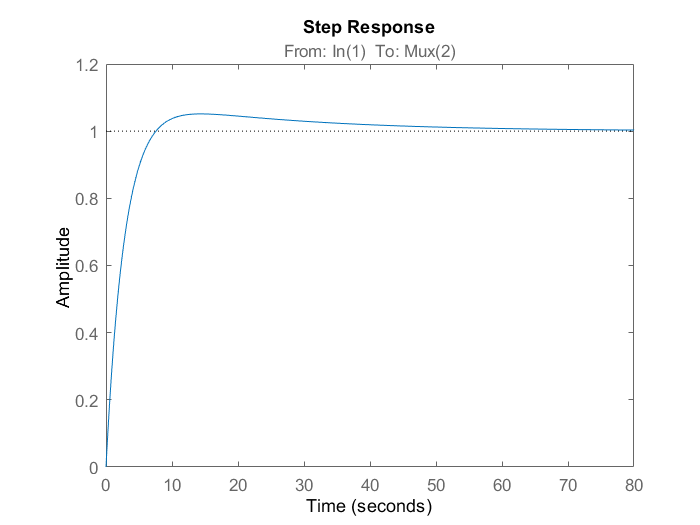

K22_mp = K2*(1+1/(T2*s));
T22_mp = feedback(G22_mp*K22_mp,1);
figure
step(T22_mp)

info = stepinfo(T22_mp)

info = struct with fields:
        RiseTime: 4.8082
    SettlingTime: 38.9408
     SettlingMin: 0.9038
     SettlingMax: 1.0514
       Overshoot: 5.1409
      Undershoot: 0
            Peak: 1.0514
        PeakTime: 14.3761


% multivariable control:
K_mp = [K11_mp, 0; 0, K22_mp]

K_mp =
 
  From input 1 to output...
       150 s + 6
   1:  ---------
         25 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       200 s + 8
   2:  ---------
         25 s
 
Continuous-time transfer function.



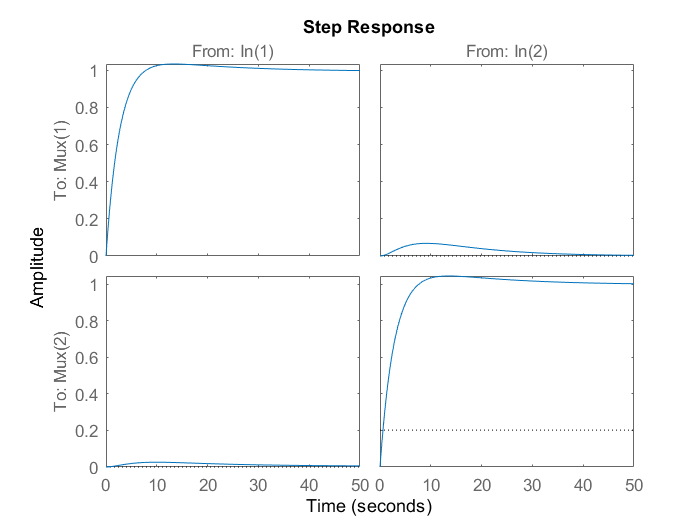

T_mp = feedback(G_mp*K_mp, eye(size(G_mp)));
figure
step(T_mp,50)

info = stepinfo(T_mp);
disp('Step response r1 -> y1:')

Step response r1 -> y1:


info(1,1)

ans = struct with fields:
        RiseTime: 4.7587
    SettlingTime: 22.9127
     SettlingMin: 0.9117
     SettlingMax: 1.0340
       Overshoot: 3.3984
      Undershoot: 0
            Peak: 1.0340
        PeakTime: 13.3089


disp('Step response r2 -> y2:')

Step response r2 -> y2:


info(2,2)

ans = struct with fields:
        RiseTime: 4.8201
    SettlingTime: 27.8436
     SettlingMin: 0.9081
     SettlingMax: 1.0445
       Overshoot: 4.4535
      Undershoot: 0
            Peak: 1.0445
        PeakTime: 13.5465


## Section

non-minphase (controller K_np)

% off-diagonal pairing 
% Controller K21 (u2 -> y1)
clear all
syms K3 K4 T3 T4 s...
     c1 d1 d2
K_np21 = K3*(1+1/(T3 * s));
G_np12 = c1/(s^2+d1*s+d2);

c1 = 0.002335; d1 = 0.05053; d2 = 0.0006119;
vpa(subs(G_np12),6)

$$ans = \frac{0.002335}{s^{2}+0.05053\,s+0.0006119}$$

[~,D_G_np12] = numden(G_np12);
F = vpa(factor(subs(D_G_np12), s, 'FactorMode','real'),6)

$$F = \left(\begin{array}{cc} s+0.0201249 & s+0.0304051 \end{array}\right)$$

%F = vpa(factor(s^2+0.05053 * s + 0.0006119, s, 'FactorMode','real'),6)
vpa(expand(F(1)*F(2)),6)

$$ans = s^{2}+0.05053\,s+0.0006119$$

L_np11 = G_np12 * K_np21;
T_np11 = (1+L_np11)\L_np11;
%visualize T_mp11
disp('T_np11:')

T_np11:


vpa(subs(simplify(expand(T_np11))),6)

$$ans = \frac{0.002335\,K_{3}\,\left(T_{3}\,s+1.0\right)}{0.002335\,K_{3}+0.0006119\,T_{3}\,s+0.05053\,T_{3}\,s^{2}+T_{3}\,s^{3}+0.002335\,K_{3}\,T_{3}\,s}$$

% extract poles:
[~,D_T_np11] = numden(T_np11)

$$D\_T\_np11 = K_{3}\,c_{1}+T_{3}\,s^{3}+T_{3}\,d_{2}\,s+T_{3}\,d_{1}\,s^{2}+K_{3}\,T_{3}\,c_{1}\,s$$

% subs(simplify(expand(D_T_np11)))
% factor(D_T_np11,s)
run("quadtank_nonminphase.m");


 Operating point search report:
---------------------------------

 Operating point search report for the Model nlQuadtank.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) nlQuadtank/h1_state
      x:          6.79      dx:     -2.95e-09 (0)
(2.) nlQuadtank/h2_state
      x:          8.78      dx:     -1.09e-08 (0)
(3.) nlQuadtank/h3_state
      x:          2.97      dx:      5.05e-09 (0)
(4.) nlQuadtank/h4_state1
      x:          4.17      dx:       1.3e-08 (0)

Inputs: 
----------
(1.) nlQuadtan

G_np = tf(sys_np);
G12_np = G_np(1,2)

G12_np =
 
  From input "u(2)" to output "Mux(1)":
           0.002335
  ---------------------------
  s^2 + 0.05053 s + 0.0006119
 
Continuous-time transfer function.



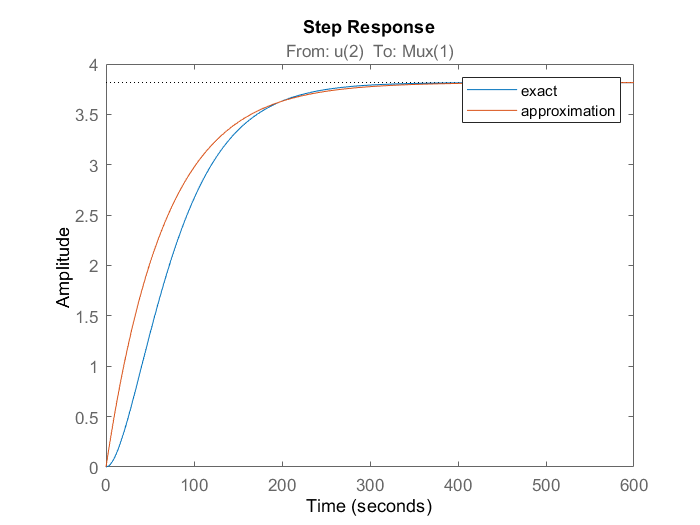

s = tf('s');
KN = 0.002335; % numerator gain of G12_np
p1 = -0.0201249; p2 = -0.0304051; % poles of G12_np
tau1 = -1/p1; tau2 = -1/p2; 
tau = tau1+tau2/2;
G12_np_approx = (KN/(p1*p2))/((tau)*s+1); % half rule with neglected delay term
figure
step(G12_np, G12_np_approx)
legend('exact','approximation');

disp('Settling time G12_np (exact):')

Settling time G12_np (exact):


stepinfo(G12_np).SettlingTime

ans = 245.6363

disp('Settling time G12_np (approximation):')

Settling time G12_np (approximation):


stepinfo(G12_np_approx).SettlingTime

ans = 258.7223

%--> Settling times are similar, approximation can be used
% --> procedure of mp Controller!
G12_np_approx

G12_np_approx =
 
     3.816
  -----------
  66.13 s + 1
 
Continuous-time transfer function.



p = -1/tau;
KN3 = KN/(p1*p2*tau);
% controller K21 --> K3 and T3
zmin = 0.59116;
factor =10; % factor for distance of zero and pole real part
K3min = (46/225 + p)/KN3           % condition I (>)

K3min = 3.2811

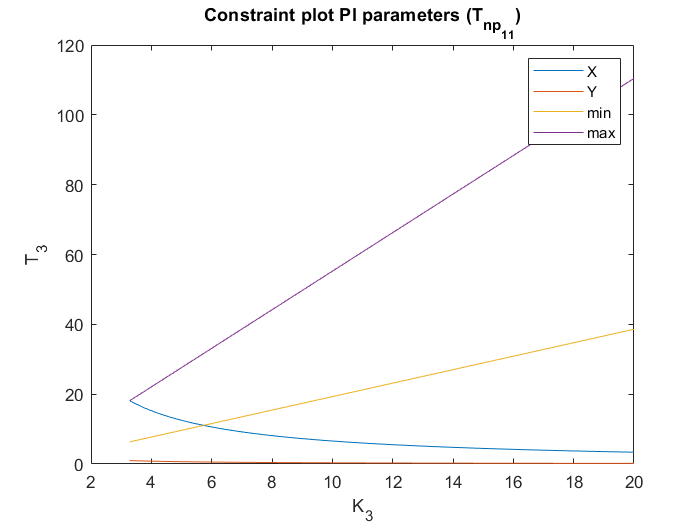

K3 = linspace(K3min,20,100);       % initialize K1 vector
T3_X = 4*(KN3*K3)./((KN3*K3-p).^2); % condition X (<)
T3_Y = 2./(factor*(KN3*K3-p));      % condition Y (<)
T3_min = KN3*K3*(225/23)^2*zmin^2;   % condition min (>)
T3_max = KN3*K3*(225/23)^2*1^2;   % condition max (>)

figure
plot(K3,T3_X,K3,T3_Y,K3,T3_min,K3,T3_max)
title('Constraint plot PI parameters (T_{np_{11}})')
xlabel('K_3')
ylabel('T_3')
legend ('X','Y','min','max')

%% Design Procedure:
% --> from graph: T3min = 6.332 (min graph at K3 = K3min) 
% Learn from design of K11!
% Choice 1: K3 = 7 (ca. 2*K2min), T3= 27 (ca. 2*T3_min(@K3=7) --> OS = 83.73%, ts = 565.96s
% rise time is 8.5s (correct order of magnitude) but OS too high --> higher T3
% Choice 2: K3 = 7, T3 = 54 =2*[Choice 1]                --> OS = 67% , ts = 229s
% Choice 3: K3 = 7, T3 = 108 =2*[Choice 2]               --> OS = 57.9% , ts = 178s
% Choice 4: K3 = 7, T3 = 250 > 2*[Choice 3]              --> OS = 52%, ts = 201.8s
% Choice 5: K3 = 3.282=K3min, T3 = 500 = 2*[Choice 4]    --> OS = 32.9%, ts = 623.6s
% Try tu use IMC tuning rules for PI (Skogestad p.57)
% Choice 6: tau_c = Theta K3 = 0.527, T3 = 66.13 = tau (ca. 125*K3)--> OS = 12.22%, ts = 227s
% Choice 7: K3 = 1.756, T3 = 125*K3 = 219.5              --> OS = 20.46%, ts = 381s
% Choice 8: K3 = 1.756, T3 = 100                         --> OS = 30.16%, ts = 211s
% if T3 is to high, Settling time increases massively because steady state error of 
% proportional controller part is corrected very slowly, however if T3 is
% too low, OS increases --> Gain < 1.756 is required to meet OS
% requirement. Gain >> 1.756 is required to meet ts requirement 
% trade off: Choice 9: tau_c = Theta --> K3 = 0.527, T3 = 72 --> OS = 9.59%, ts = 228.5s
% Or : Choice 10: tau_c = 0.5*Theta --> K3 = 0.703, T3 such that OS around 10% (try
% and error) --> T3 = 90.92                                  --> OS = 9.85%, ts = 214.75s
%--------> Choice 10 is about as good as it gets  

% Test controller
K3 = 0.703 

K3 = 0.7030

T3 = 66.13*1.375

T3 = 90.9288

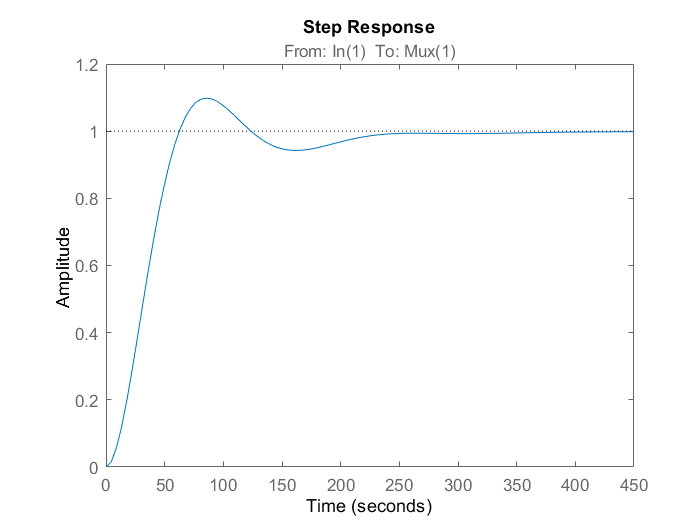

K21_np = K3*(1+1/(T3*s));
T11_np = feedback(G12_np * K21_np, 1);
figure
step(T11_np)

stepinfo(T11_np)

ans = struct with fields:
        RiseTime: 41.9127
    SettlingTime: 214.7475
     SettlingMin: 0.9052
     SettlingMax: 1.0985
       Overshoot: 9.8505
      Undershoot: 0
            Peak: 1.0985
        PeakTime: 85.7615


## Section

K12

% L22 = G21_np*K12_np
G21_np = zpk(G_np(2,1))

G21_np =
 
  From input "u(1)" to output "Mux(2)":
         0.0010296
  -----------------------
  (s+0.01766) (s+0.01217)
 
Continuous-time zero/pole/gain model.



KN = 0.0010296; % numerator gain of G21_np
p1 = -0.01217; p2 = -0.01766; % poles of G21_np
tau1 = -1/p1; tau2 = -1/p2; 
tau = tau1+tau2/2; % half rule 
Theta = tau2/2;

%% Design Procedure:
% Learn from design of K21!
% Try tu use IMC tuning rules for PI (Skogestad p.57)
% Choice 1: tau_c = Theta
% --> K4 = 0.4073, T4 = 110.4818 --> OS=11.95%, ts=387.166s
% Choice 2: tau_c = 0.5*Theta
% --> K4 = 0.543, T4 = 149.15 (so that OS 10%) --> OS=9.89%, ts=364.7s
% Choice 3: tau_c = 0.25*Theta
% --> K4 = 0.6516, T4 = 181.1902 (so that OS 10%) --> OS=9.98%, ts=357.19s 
%--------> Choice 3 is about as good as it gets  
% Test controller
tau_c = 0.25*Theta;
K4 = (1/(KN/(p1*p2)))*tau/(tau_c+Theta)

K4 = 0.6516

T4 = min([tau, 4*(tau_c+Theta)])*1.64

T4 = 181.1902

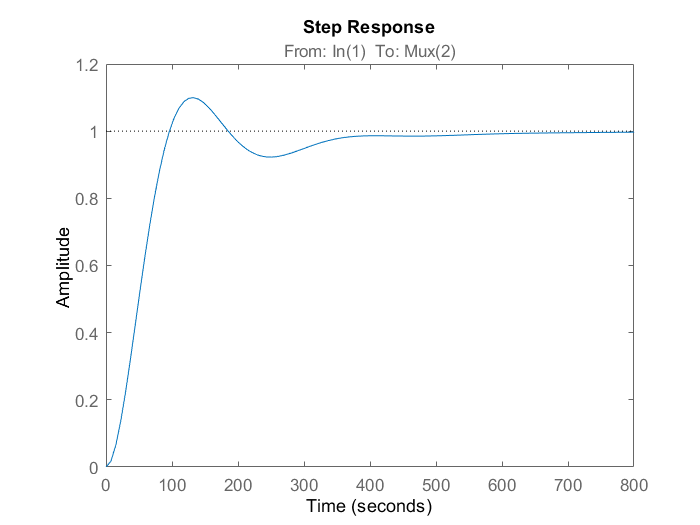


K12_np = K4*(1+1/(T4*s));
T22_np = feedback(G21_np * K12_np, 1);
figure
step(T22_np)

stepinfo(T22_np)

ans = struct with fields:
        RiseTime: 64.6171
    SettlingTime: 357.1868
     SettlingMin: 0.9228
     SettlingMax: 1.0998
       Overshoot: 9.9842
      Undershoot: 0
            Peak: 1.0998
        PeakTime: 132.6899


% multivariable control:
K_np = [0, K12_np; K21_np, 0]

K_np =
 
  From input 1 to output...
   1:  0
 
       63.92 s + 0.703
   2:  ---------------
           90.93 s
 
  From input 2 to output...
       118.1 s + 0.6516
   1:  ----------------
           181.2 s
 
   2:  0
 
Continuous-time transfer function.



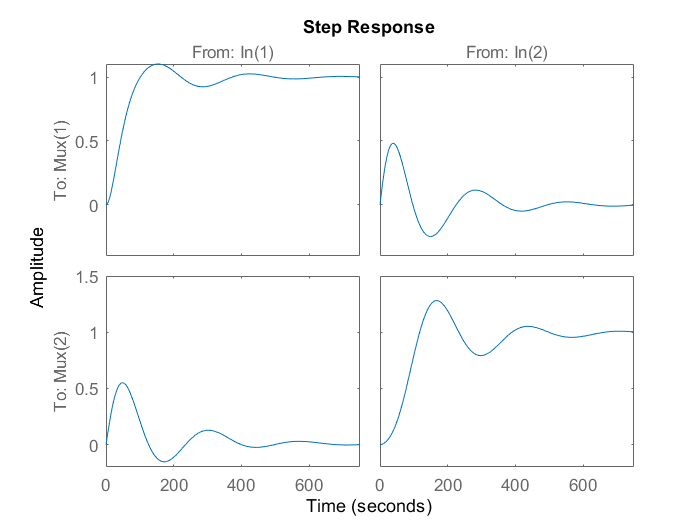

T_np = feedback(G_np*K_np, eye(size(G_np)));
figure
step(T_np,750)

info = stepinfo(T_np);
disp('Step response r1 -> y1:')

Step response r1 -> y1:


info(1,1)

ans = struct with fields:
        RiseTime: 67.6672
    SettlingTime: 451.6199
     SettlingMin: 0.9159
     SettlingMax: 1.1025
       Overshoot: 10.2498
      Undershoot: 0
            Peak: 1.1025
        PeakTime: 152.8634


disp('Step response r2 -> y2:')

Step response r2 -> y2:


info(2,2)

ans = struct with fields:
        RiseTime: 73.1408
    SettlingTime: 627.2668
     SettlingMin: 0.7916
     SettlingMax: 1.2813
       Overshoot: 28.1280
      Undershoot: 0
            Peak: 1.2813
        PeakTime: 166.4513
